# Experiment 06-Solving linear differential equations using 'dsolve'

## Inserting and solving a equation in matlab:

### Question 1:

solve:   $\frac{\textrm{dy}}{\textrm{dx}}=x+y$

(i) with $y\left(0\right)=0$  and store the solution as solution(x):

(ii)find value at x=1.5 and plot the solution in interval[0,1.5]

% (i)
%Do not use "clear" while performing matlab grader
syms y(x)
DiffEq1=diff(y,x)==x+y

$$DiffEq1(x) = \frac{\partial }{\partial x}y\left(x\right)=x+y\left(x\right)$$

sol(x)=dsolve(DiffEq1)

$$sol(x) = C_{1}\,{\mathrm{e}}^{x}-x-1$$

ic1=y(0)==0;
solution(x)=dsolve(DiffEq1,ic1)

$$solution(x) = {\mathrm{e}}^{x}-x-1$$


%(ii)
ii_solution=vpa(solution(1.5),5)%vpa has significant digits upto 32 here we save it till 5 digits

$$ii\_solution = 1.9817$$

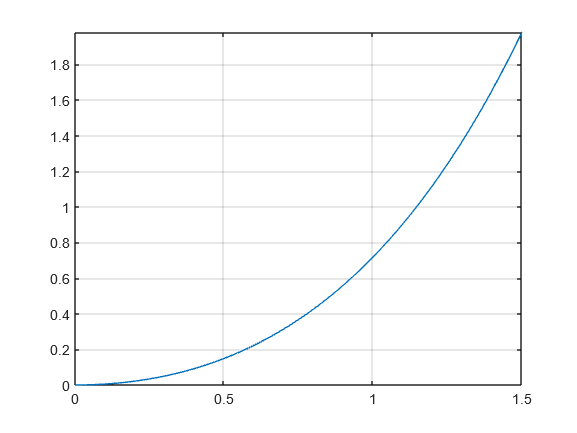


fplot(solution,[0,1.5])
grid on

### Question 2:

solve: $\frac{\textrm{dy}}{\textrm{dx}}+\frac{y}{x}=e^x$ 

clear
syms y(x)
a=diff(y,x)+(y/x)==exp(x)

$$a(x) = \frac{y\left(x\right)}{x}+\frac{\partial }{\partial x}y\left(x\right)={\mathrm{e}}^{x}$$

sol(x)=dsolve(a)

$$sol(x) = \frac{C_{1}}{x}+\frac{{\mathrm{e}}^{x}\,\left(x-1\right)}{x}$$

### Question 3:

solve: $\left(1+x^2 \right)\textrm{dy}+\left(2\textrm{xy}-4x^3 \right)\textrm{dx}=0$ with y(0)=1

store it as solution(x)

store solution(1)=s_1

plot the graph from 1,3

clear
syms y(x)
Diffeq=(1+x^2)*diff(y,x)==(-2*x*y+4*x^3)

$$Diffeq(x) = \left(x^{2}+1\right)\,\frac{\partial }{\partial x}y\left(x\right)=4\,x^{3}-2\,x\,y\left(x\right)$$

ic1=y(0)==1

$$ic1 = y\left(0\right)=1$$

solution(x)=dsolve(Diffeq,ic1)

$$solution(x) = \frac{x^{4}+1}{x^{2}+1}$$

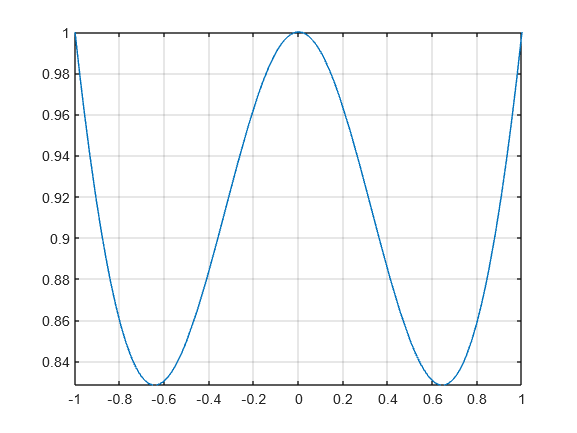

fplot(solution(x),[-1,1])
grid on